# Train DQN Agent for Lane Keeping Assist

This example shows how to train a Deep Q-Learning Network (DQN) agent for lane keeping assist (LKA) in Simulink®. For more information on DQN agents, see [Deep Q-Network Agents](docid:rl_ug#mw_101bb08b-96e7-439b-a628-afff98ca3b6f).

## Simulink Model for Ego Car

The reinforcement learning environment for this example is a simple bicycle model for ego vehicle dynamics. The training goal is to keep the ego vehicle traveling along the centerline of the lanes by adjusting the front steering angle. This example uses the same vehicle model as in [Lane Keeping Assist System Using Model Predictive Control](docid:mpc_ug#mw_a74af043-f834-4024-ae3a-ab934fdf6031) example.

m = 1575;   % total vehicle mass (kg)
Iz = 2875;  % yaw moment of inertia (mNs^2)
lf = 1.2;   % longitudinal distance from center of gravity to front tires (m)
lr = 1.6;   % longitudinal distance from center of gravity to rear tires (m)
Cf = 19000; % cornering stiffness of front tires (N/rad)
Cr = 33000; % cornering stiffness of rear tires (N/rad)
Vx = 15;    % longitudinal velocity (m/s)

Define the sample time, `Ts`, and simulation duration, `T`, in seconds.

Ts = 0.1;
T = 15;

The output of the LKA system is the front steering angle of the ego car. Considering the physical limitations of the ego car, the steering angle is constrained to the range [-0.5,0.5] rad.

u_min = -0.5;
u_max = 0.5;

The curvature of the road is defined by a constant 0.001($m^{-1}$). The initial value for lateral deviation is 0.2 m and the initial value for relative yaw angle is -0.1 rad.

rho = 0.001;
e1_initial = 0.2;
e2_initial = -0.1;

Open the model.

mdl = 'rlLKAMdl';
open_system(mdl);
agentblk = [mdl '/RL Agent'];

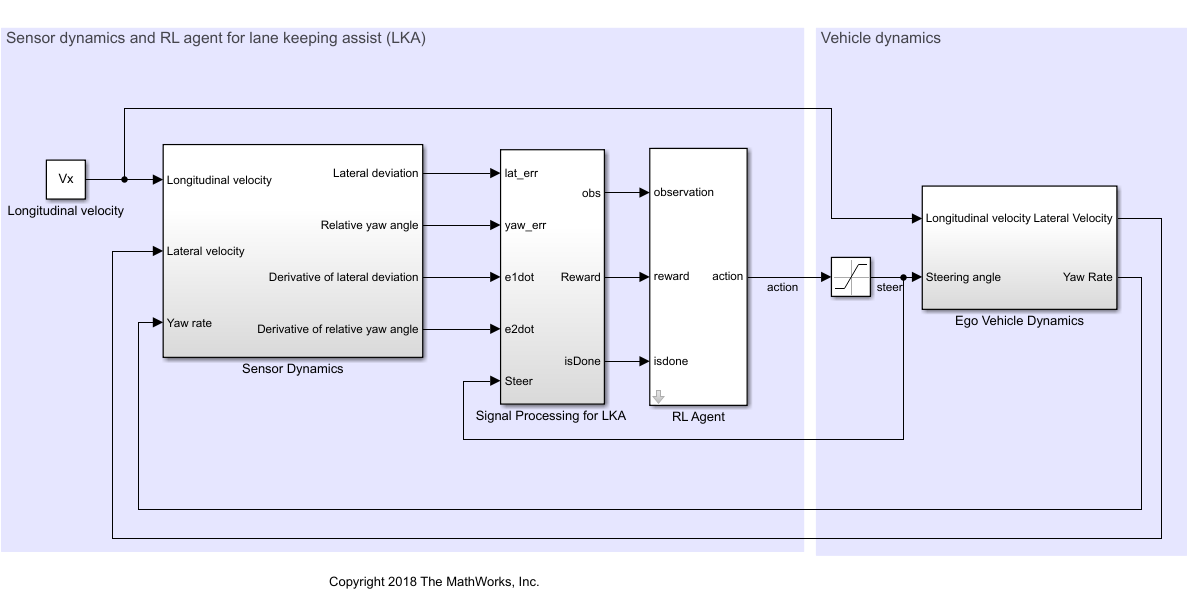

For this model:

- The steering-angle action signal from the agent to the environment is from -15 deg to 15 deg.

- The observations from the environment are the lateral deviation $e_1$, relative yaw angle $e_2$, their derivatives $\dot{e}_1$ and $\dot{e}_2
$, and their integrals $\int e_1$ and $\int e_2$. 

- The simulation is terminated when lateral deviation $|e_1|>1.$

- The reward $r_t$, provided at every time step $t$, is:


$$r_t = -(10e_1^2+5e_2^2+2u^2+5\dot{e}_1^2+5\dot{e}_2^2)$$


where $u$ is the control input from the previous time step $t-1$.

## Create Environment Interface

Create a reinforcement learning environment interface for the ego vehicle. To do so, first create the observation and action specifications.

% create observation info
observationInfo = rlNumericSpec([6 1],'LowerLimit',-inf*ones(6,1),'UpperLimit',inf*ones(6,1));
observationInfo.Name = 'observations';
observationInfo.Description = 'information on lateral deviation and relative yaw angle';
% create action Info
actionInfo = rlFiniteSetSpec((-15:15)*pi/180);
actionInfo.Name = 'steering';
% define environment
env = rlSimulinkEnv(mdl,agentblk,observationInfo,actionInfo);

The interface has a discrete action space where the agent can apply one of 31 possible steering angles from -15 degrees to 15 degrees.

To define the initial condition for lateral deviation and relative yaw angle, specify an environment reset function using an anonymous function handle. 

% randomize initial values for lateral deviation and relative yaw angle
env.ResetFcn = @(in)localResetFcn(in);

Fix the random generator seed for reproducibility.

rng(0);

## Create DQN agent

A DQN agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

L = 24; % number of neurons
statePath = [
    imageInputLayer([6 1 1], 'Normalization', 'none', 'Name', 'state')
    fullyConnectedLayer(L, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(L, 'Name', 'fc2')
    additionLayer(2,'Name','add')
    reluLayer('Name','relu2')
    fullyConnectedLayer(L, 'Name', 'fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(1, 'Name', 'fc4')];

actionPath = [
    imageInputLayer([1 1 1], 'Normalization', 'none', 'Name', 'action')
    fullyConnectedLayer(L, 'Name', 'fc5')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);    
criticNetwork = connectLayers(criticNetwork,'fc5','add/in2');

View the critic network configuration.

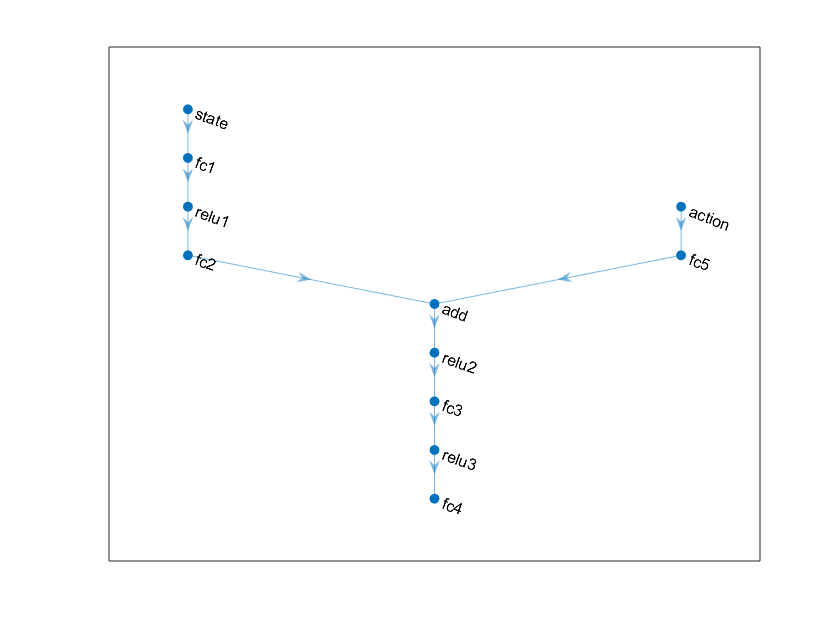

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'L2RegularizationFactor',1e-4);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you obtain from the environment interface. For more information, see [`rlRepresentation`](docid:rl_ref#mw_453a7f45-3761-4387-9e1d-4c90ed8b5b57).

critic = rlRepresentation(criticNetwork,criticOptions,'Observation',{'state'},observationInfo,'Action',{'action'},actionInfo);

To create the DQN agent, first specify the DQN agent options using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e).

agentOptions = rlDQNAgentOptions(...
    'SampleTime',Ts,...
    'UseDoubleDQN',true,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.99,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',64);

Then, create the DQN agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 5000 episodes, with each episode lasting at most 150 time steps.

- Display the training progress in the Episode Manager dialog box.

- Stop training when the episode reward reaches -1. 

- Save a copy of the agent for each episode where the cumulative reward is greater than `-2.5`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(T/Ts);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue', -1,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue', -2.5);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOpts);
else
    % Load pretrained agent for the example.
    load('SimulinkLKADQN.mat','agent')  
end

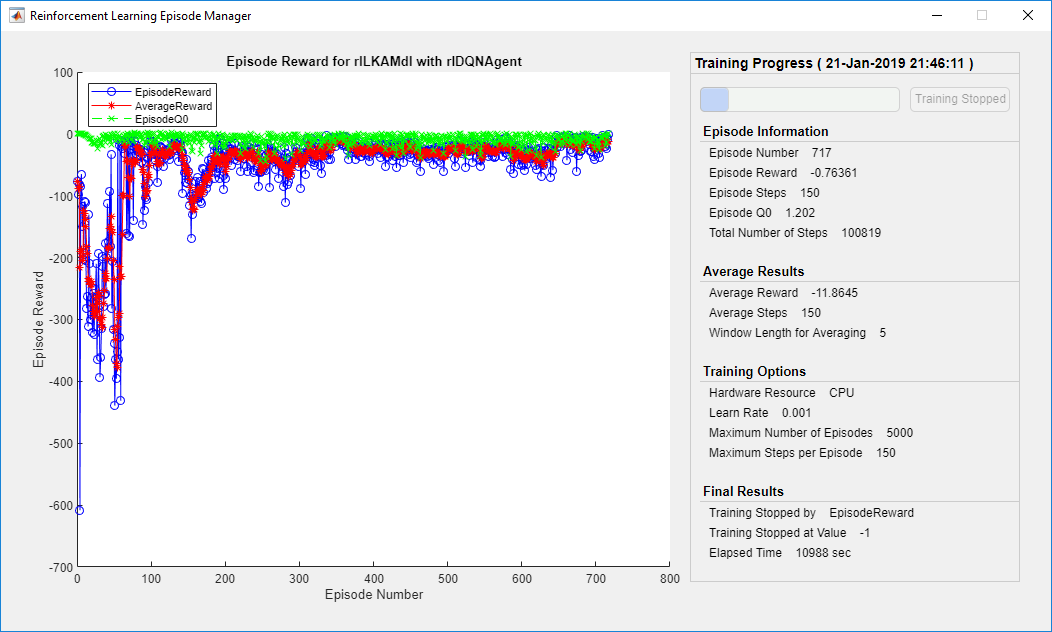

## Simulate DQN Agent

To validate the performance of the trained agent, uncomment the following two lines and simulate it within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

% simOptions = rlSimulationOptions('MaxSteps',maxsteps);
% experience = sim(env,agent,simOptions);

To demonstrate the trained agent on deterministic initial conditions, simulate the model in Simulink. 

e1_initial = -0.4;
e2_initial = 0.2;
sim(mdl);

As shown below, the lateral error (middle plot) and relative yaw angle (bottom plot) are both driven to zero. The vehicle starts from off centerline (-0.4 m) and non-zero yaw angle error (0.2 rad). The lane keeping assist makes the ego car traveling along the centerline around 2.5 seconds. The steering angle (top plot) shows that the controller reaches steady-state after 2 seconds.  

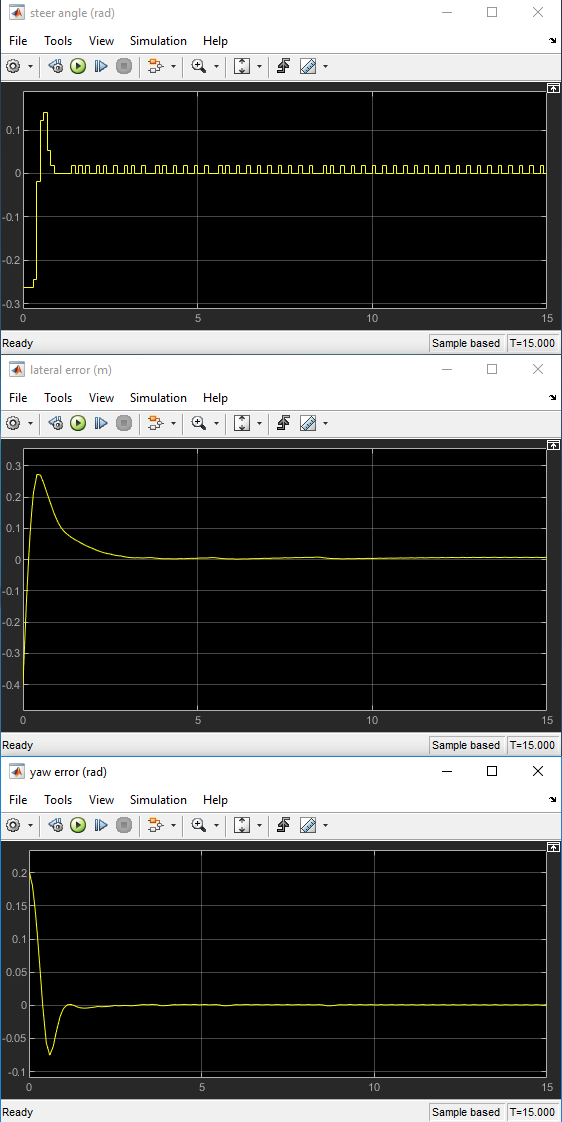

Close the Simulink model. 

bdclose(mdl);

## Local function

function in = localResetFcn(in)
% reset
in = setVariable(in,'e1_initial', 0.5*(-1+2*rand)); % random value for lateral deviation
in = setVariable(in,'e2_initial', 0.1*(-1+2*rand)); % random value for relative yaw angle
end

*Copyright 2018-2019 The MathWorks, Inc.*

*MATLAB and Simulink are registered trademarks of The MathWorks, Inc. Please see* [*www.mathworks.com/trademarks*](https://www.mathworks.com/trademarks) *for a list of other trademarks owned by The MathWorks, Inc. Other product or brand names are trademarks or registered trademarks of their respective owners.*